% AAE 532 HW 9 Problem 3
% Tomoki Koike
close all; clear all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Fall\AAE532\matlab\outputs\ps9';
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% Set constants
planet_consts = setup_planetary_constants();  % Function that sets up all the constants in the table 
sun = planet_consts.sun;  % structure of sun
earth = planet_consts.earth;  % structure of earth
mercury = planet_consts.mercury;  % structure of mercury 
venus = planet_consts.venus;  % structure of venus
jupiter = planet_consts.jupiter;  % structure of Juipter
G = 6.6743015e-20;  % Gravitational constant [km^3/kg/s^2]

% (a)

mu_jup = jupiter.gp;

% Remus 
a_R = 15 * jupiter.mer

a_R = 1072380

R_R = 3000;
e_R = 0.25;
mu_R = 1e5;
p_R = a_R * (1 - e_R^2)

p_R = 1.0054e+06

b_R = a_R * sqrt(1 - e_R^2)

b_R = 1.0383e+06

rp_R = a_R * (1 - e_R)

rp_R = 804285

ra_R = a_R * (1 + e_R)

ra_R = 1340475


% Spacecraft 
r_p = 7.5 * jupiter.mer

r_p = 536190

e_0 = 0.5;
a_0 = r_p / (1 - e_0)

a_0 = 1072380

p_0 = a_0 * (1 - e_0^2)

p_0 = 804285

% True anomaly at the semi-minor axis of Remus
TA_Rb = acosd(1 / e_R * (p_R / a_R - 1))

TA_Rb = 104.4775

TA_0b = acosd(1 / e_0 * (p_0 / a_R - 1))

TA_0b = 120.0000

Domega_0 = -TA_0b + TA_Rb

Domega_0 = -15.5225

% % Plot
% % Jupiter
% angles = 0:0.1:360;
% Xj = jupiter.mer * cosd(angles); Yj = jupiter.mer * sind(angles);
% % Remus 
% Rrem = p_R ./ (1 + e_R * cosd(angles));
% Xrem = Rrem .* cosd(angles); Yrem = Rrem .* sind(angles);
% % spacecraft
% Rsc = p_0 ./ (1 + e_0 * cosd(angles - Domega_0));
% Xsc = Rsc .* cosd(angles); Ysc = Rsc .* sind(angles);
% 
% fig = figure("Renderer","painters","Position",[10, 10, 900, 700]);
%     plot(Xj,Yj, '-', 'LineWidth', 3)
%     hold on; grid on; grid minor; box on; axis equal; 
%     plot(Xrem, Yrem)
%     plot(Xsc, Ysc) 
%     
%     plot([-ra_R, rp_R], [0, 0], '-k')
%     plot([-a_R*e_R, -a_R*e_R], [-b_R, b_R], '-k')
%     hold off
%     title('The Original Orbits of Remus and Spacecraft About Jupiter  - T. Koike')
%     xlabel('$\hat{e}$ [km]')
%     ylabel('$\hat{p}$ [km]')
% saveas(fig, fullfile(fdir, "p3_remus_sc_original.png"))

% (b)
% Spacecraft
r_minus = a_R;
v_minus = vis_viva(r_minus, a_0, mu_jup)

v_minus = 10.8702

h_minus = sqrt(mu_jup * p_0)

h_minus = 1.0095e+07

FPA_minus = acosd(h_minus / r_minus / v_minus)

FPA_minus = 30.0000

TA_minus = TA_0b;

% Remus
v_R = vis_viva(r_minus, a_R, mu_jup)

v_R = 10.8702

FPA_R = acosd(sqrt(mu_jup * p_R) / r_minus / v_R)

FPA_R = 14.4775

% (c)

v_minus_vec = v_minus * [sind(FPA_minus), cosd(FPA_minus)]

v_minus_vec =     5.4351    9.4138


v_R_vec = v_R * [sind(FPA_R), cosd(FPA_R)]

v_R_vec =     2.7175   10.5250


v_inf_R_vec = v_minus_vec - v_R_vec

v_inf_R_vec =     2.7175   -1.1112


v_inf_R = norm(v_inf_R_vec)

v_inf_R = 2.9359

% (d)

% Hyperbola
E_fb = v_inf_R^2 / 2;
a_fb = -mu_R / 2 / E_fb

a_fb = -1.1601e+04

rp_fb = R_R + 1500

rp_fb = 4500

e_fb = 1 - rp_fb / a_fb

e_fb = 1.3879

delta = 2 * asind(1 / e_fb)

delta = 92.1949

v_inf_R_plus_vec = v_inf_R_vec * [cosd(-delta), sind(-delta); -sind(-delta), cosd(-delta)]

v_inf_R_plus_vec =    -1.2144   -2.6730


v_plus_vec = v_R_vec + v_inf_R_plus_vec

v_plus_vec =     1.5031    7.8520


v_plus = norm(v_plus_vec)

v_plus = 7.9946

r_plus = r_minus;
FPA_plus = atand(v_plus_vec(1) / v_plus_vec(2))

FPA_plus = 10.8371

% True anomaly
temp = r_plus * v_plus^2 / mu_jup;
TA_plus = atan_dbval( temp*sind(FPA_plus)*cosd(FPA_plus) / ( temp*cosd(FPA_plus)^2 - 1 ), "deg")

TA_plus =   -11.7978  168.2022


TA_plus = TA_plus(TA_plus == max(TA_plus))

TA_plus = 168.2022

h_plus = r_plus*v_plus*cosd(FPA_plus)

h_plus = 8.4203e+06

p_plus = h_plus^2 / mu_jup

p_plus = 5.5955e+05

e_plus = 1/cosd(TA_plus) * (p_plus/r_plus - 1)

e_plus = 0.4885

a_plus = p_plus / (1 - e_plus^2)

a_plus = 7.3496e+05

r_p_plus = a_plus * (1 - e_plus)

r_p_plus = 3.7590e+05

r_a_plus = a_plus * (1 + e_plus)

r_a_plus = 1.0940e+06

IP_plus = 2*pi * sqrt(a_plus^3 / mu_jup)

IP_plus = 3.5170e+05

IP_plus_days = IP_plus / 60 / 60 / 24 

IP_plus_days = 4.0705

Domega = TA_minus - TA_plus

Domega = -48.2022

Dv_eq_vec = v_plus_vec - v_minus_vec

Dv_eq_vec =    -3.9320   -1.5618


Dv_eq = norm(Dv_eq_vec)

Dv_eq = 4.2308

alpha = acosd(dot(v_minus_vec, Dv_eq_vec) / Dv_eq / v_minus)

alpha = 141.6638

Dv_eq_vec_VBN = Dv_eq * [cosd(alpha), -sind(alpha)]

Dv_eq_vec_VBN =    -3.3186   -2.6243


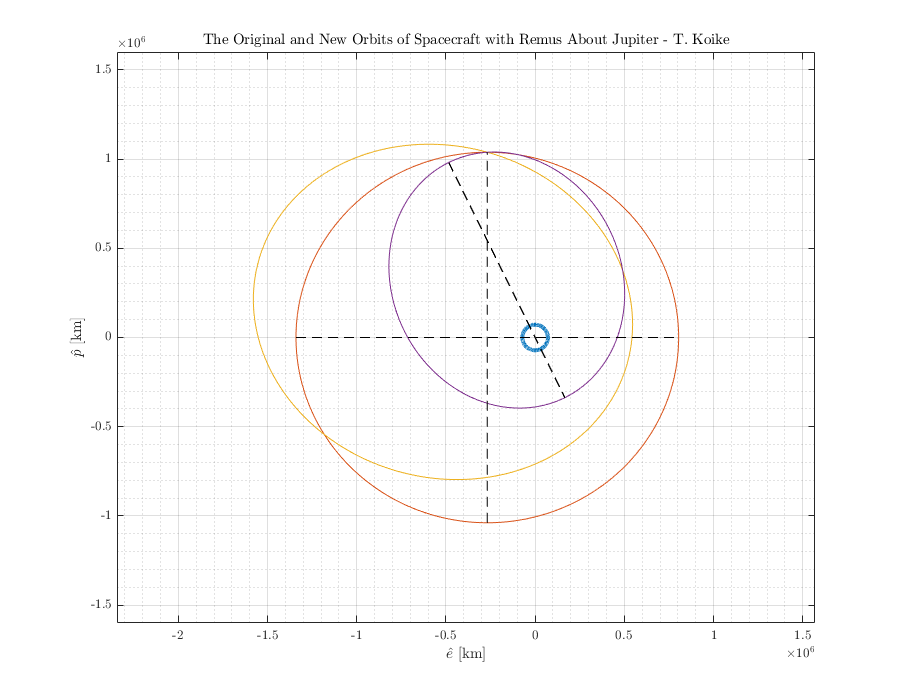

% Plot

% (i) Jupiter
angles = 0:0.1:360;
Xj = jupiter.mer * cosd(angles); Yj = jupiter.mer * sind(angles);
% Remus 
Rrem = p_R ./ (1 + e_R * cosd(angles));
Xrem = Rrem .* cosd(angles); Yrem = Rrem .* sind(angles);
% spacecraft
Rsc = p_0 ./ (1 + e_0 * cosd(angles - Domega_0));
Xsc = Rsc .* cosd(angles); Ysc = Rsc .* sind(angles);

% new orbit
Rnew = p_plus ./ (1 + e_plus*cosd(angles - (Domega + Domega_0)));
Xnew = Rnew .* cosd(angles); Ynew = Rnew .* sind(angles);

fig = figure("Renderer","painters","Position",[10, 10, 900, 700]);
    plot(Xj,Yj, '-', 'LineWidth', 3)
    hold on; grid on; grid minor; box on; axis equal; 
    plot(Xrem, Yrem)
    plot(Xsc, Ysc) 
    plot(Xnew, Ynew)
    plot([-ra_R, rp_R], [0, 0], '--k')
    plot([-a_R*e_R, -a_R*e_R], [-b_R, b_R], '--k')
    
    r_a_plus_vec = r_a_plus * [-cosd(Domega + Domega_0), -sind(Domega + Domega_0)];
    r_p_plus_vec = r_p_plus * [cosd(Domega + Domega_0), sind(Domega + Domega_0)];
    temp = vertcat(r_a_plus_vec, r_p_plus_vec);
    plot(temp(:, 1), temp(:, 2), '--k', "LineWidth", 1)
    
    hold off
    ylim([-1.6e6, 1.6e6])
    title('The Original and New Orbits of Spacecraft with Remus About Jupiter  - T. Koike')
    xlabel('$\hat{e}$ [km]')
    ylabel('$\hat{p}$ [km]')
saveas(fig, fullfile(fdir, "p3_jupCenter.png"))

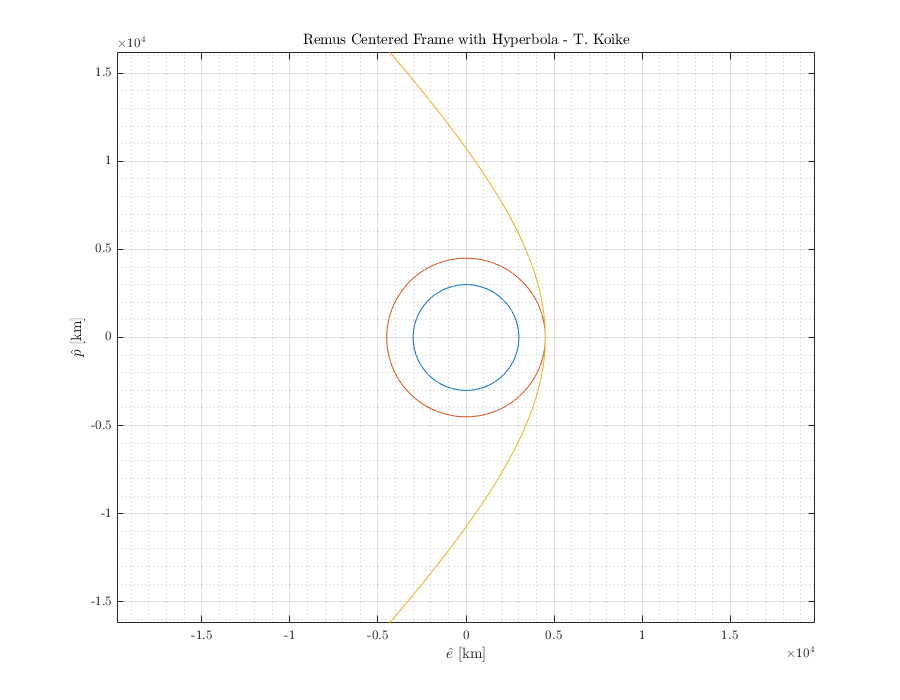

% (ii)
% moon
angles = 0:0.1:360;
XR = R_R * cosd(angles); YR = R_R * sind(angles);

% moon parking orbit
Xpo = (rp_fb) * cosd(angles); Ypo = rp_fb * sind(angles);

% hyperbola
angles = -105:0.1:105;
Rhyp = a_fb*(1 - e_fb^2) ./ (1 + e_fb * cosd(angles));
Xhyp = Rhyp .* cosd(angles);  Yhyp = Rhyp .* sind(angles);

fig = figure("Renderer","painters","Position",[10, 10, 900, 700]);
    plot(XR,YR)
    hold on; grid on; grid minor; box on; axis equal; 
    plot(Xpo, Ypo)
    plot(Xhyp, Yhyp)
    hold off
    xlabel('$\hat{e}$ [km]')
    ylabel('$\hat{p}$ [km]')
    title("Remus Centered Frame with Hyperbola - T. Koike")
saveas(fig, fullfile(fdir, "p3_remusCenter.png"));